### Aliasing

L'aliasing consiste nello *spostamento in frequenza* di un segnale ricostruito utilizzando campioni presi con frequenza che non soddisfa il criterio di Nyquist $f_c \ge 2f_{\mathrm{M}}$

In questa demo creiamo una sinusoide a frequenza $f_M$ e ne visualizziamo lo **spettro**, cioè la trasformata di Fourier. 

Poi l'ascoltiamo con il player di suono. In seguito la campioniamo e poi interpoliamo i campioni ottenuti ed infine ascoltiamo il segnale ottenuto e ne visualizziamo lo spettro.

Osserveremo che, se $f_c$ è troppo bassa, il segnale riprodotto si sposterà in frequenza.

Notiamo che in Matlab, anche il segnale "originale" è un segnale campionato (non può essere altrimenti), ma la sua frequenza di campionamento $f_{\textrm{start}}$è molto grande, 100kHz.

Noi elimineremo una parte dei campioni del segnale "originale" per simulare una diversa frequenza di campionamento. 

Se conserviamo un campione su $N$ la frequenza di campionamento diventa $f_{c\;} =\frac{f_{\textrm{start}} }{N}$

clear variables; clc

fStart = 1e5;
Delta = 1e-5;
T_end= 1;
T= 0:Delta:T_end;

fM = 770;

x = cos(2*pi*fM*T);
soundsc(x,fStart)
pause(T_end+0.1)

Mostriamo lo spettro del segnale $x$

A questo scopo si usa l'algoritmo Fast Fourier Transform, che produce lo spettro del segnale nell'intervallo $\left(-\frac{f_c }{2},\frac{f_c }{2}\right)$

M = 2^nextpow2(numel(T)); % Numero di punti della FFT
X = Delta*fft(x,M);
F = linspace(-fStart/2,fStart/2,M); % Qui si usa fstart perche x è campionato con tale freq
figure; subplot(121)  
plot(F,fftshift(abs(X)));
axis([0 fM*1.1 0 0.5])

xlabel('f [Hz]')
grid minor;
subplot(122);

Scegliamo una porzione di segnale da visualizzare nel tempo

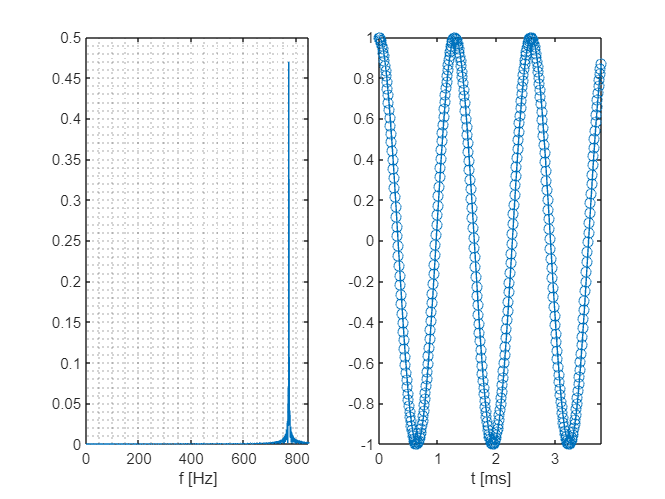

TMax = 0.0038; 
Tms = T(T<TMax);
xms = x(T<TMax);
plot(1e3*Tms, xms, '-o'); xlabel('t [ms]')
axis([0 TMax*1e3 -1 1]);

Calcoliamo ora qual è il massimo fattore di sottocampionamento che possiamo usare senza creare aliasing.

La nuova frequenza di campionamento è 


$$f_c =\frac{f_{\textrm{start}} }{N}$$


e deve essere almeno il doppio di $f_M$


$$\begin{array}{l}
\frac{f_{\textrm{start}} }{N}\ge 2f_M \\
N\le f_{\frac{\textrm{start}}{2f_M }} 
\end{array}$$


Quindi il massimo sottocampionamento che NON produce aliasing è 

maxSubSampling = floor(fStart/(2*fM))

maxSubSampling = 64

Ora vediamo che succede usando diversi valori di sottocampionamento


subsampling = 79;

fprintf('La frequenza di campionamento è ora %6.3f Hz\n', fStart/subsampling);

La frequenza di campionamento è ora 1265.823 Hz


fprintf('La massima frequenza del segnale è %6.3f Hz\n', fM);

La massima frequenza del segnale è 770.000 Hz


Sottocampioniamo il segnale e modifichiamo l'asse dei tempi:

xs = x(1:subsampling:end);
TCS = Delta*subsampling;
FCS = 1/TCS;
TS_end= 1;
TS= 0:TCS:TS_end;
soundsc(xs,FCS)


Tracciamo lo spettro ed il segnale ricostruito

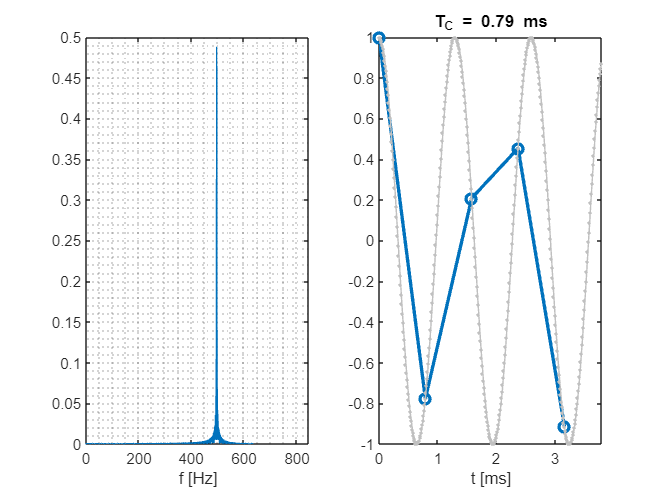

MS = 2^nextpow2(numel(TS));
XS = TCS*fft(xs,MS);
FS = linspace(-FCS/2,FCS/2,MS);
figure; subplot(121)
plot(FS,fftshift(abs(XS)));
xlabel('f [Hz]')
axis([0 fM*1.1 0 0.5])
%set(gca,'XTick',-5e3:1e3:5e3);
grid minor;
subplot(122);
TSms = TS(TS<TMax);
xsms = xs(TS<TMax);
plot(1e3*TSms, xsms, '-o', 'LineWidth',2); 
hold on;
plot(1e3*Tms, xms, '.-', 'Color', '#C0C0C0', 'LineWidth',0.2);
xlabel('t [ms]')
axis([0 TMax*1e3 -1 1]);
title(sprintf('T_C = %3.2f ms',TCS*1e3))